Lognormal Distribution

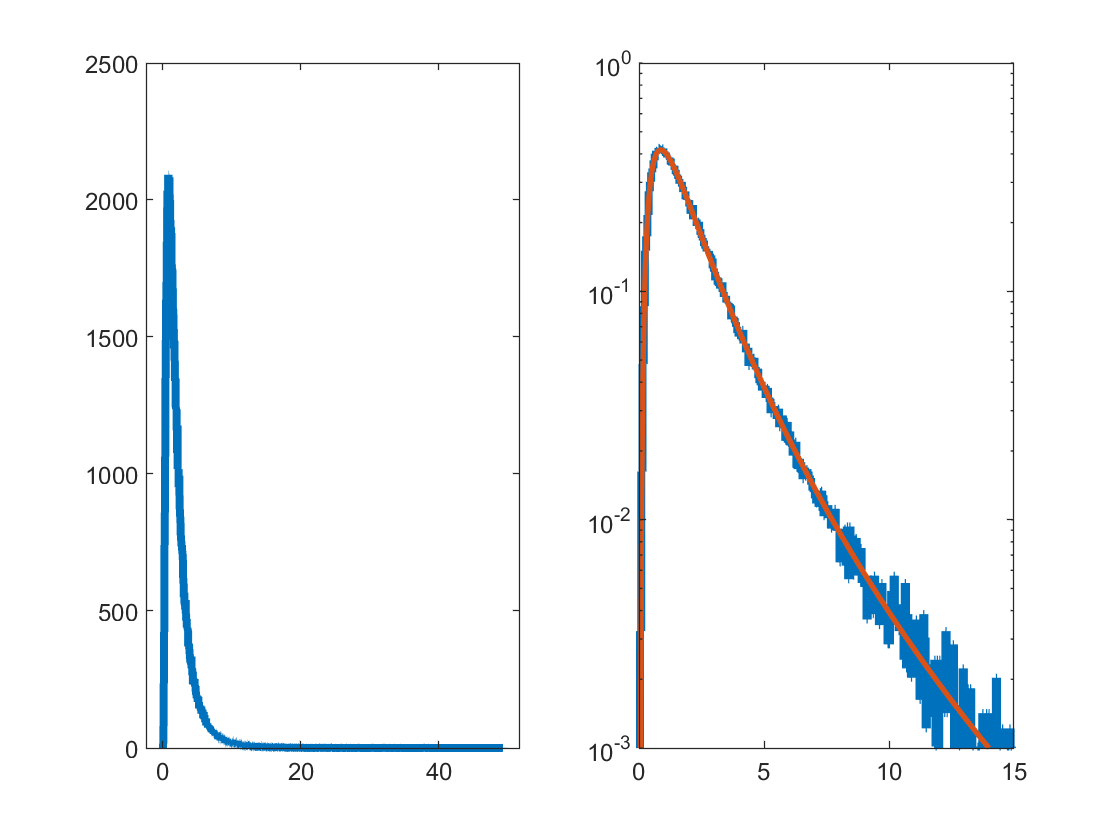

logd = random('Lognormal',0.5,0.8,[1,100000]);
subplot(1,2,1)
histogram(logd,1000,'DisplayStyle',"stairs",'LineWidth',3)
subplot(1,2,2)
histogram(logd,1000,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on
logx = linspace(0,50,1000);
logN = makedist("Lognormal",'mu',0.5,'sigma',0.8);
plot(logx,pdf(logN,logx),"LineWidth",2)
set(gca,'YScale','log')
ylim([1e-3,1])
xlim([0,15])
hold off

Exponential Distribution

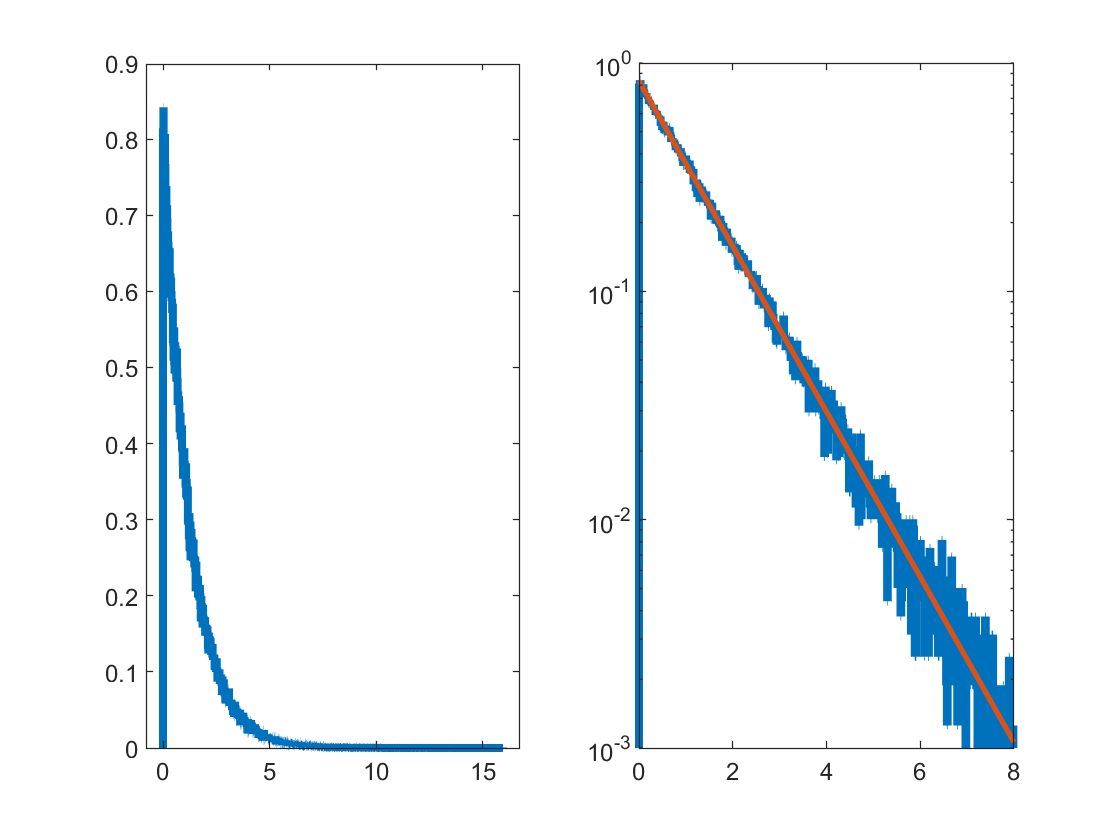

expd = exprnd(1.2,[1,100000]);
subplot(1,2,1)
histogram(expd,1000,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
subplot(1,2,2)
histogram(expd,1000,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on
expx = linspace(0,30,1000);
expD = makedist("Exponential",'mu',1.2);
plot(expx,pdf(expD,expx),"LineWidth",2);
set(gca,'YScale','log')
ylim([1e-3,1])
xlim([0,8])
hold off

A. I would choose 10 as my value for my hypothetical measurement.

B. What is the probability that this data set of Lognormal Distribution with mean as 0.5 and sigma as 0.8 produces a signal that is equally or more signal-like than what it is like?

C. $\int_{10}^{\infty } \frac{1}{x\sigma \sqrt{2\pi }}e^{-\frac{{\left(\ln \left(x\right)-\mu \right)}^2 }{2\sigma^2 }}$

D.

c = cdf(logN, 10) % P(x) = e^((-ln(x)-u)^2)/(2s^2))/(x*s*sqrt(2*pi))

c = 0.9879

E.

sigmalogN = norminv(c)

sigmalogN = 2.2532

Poisson Distribution

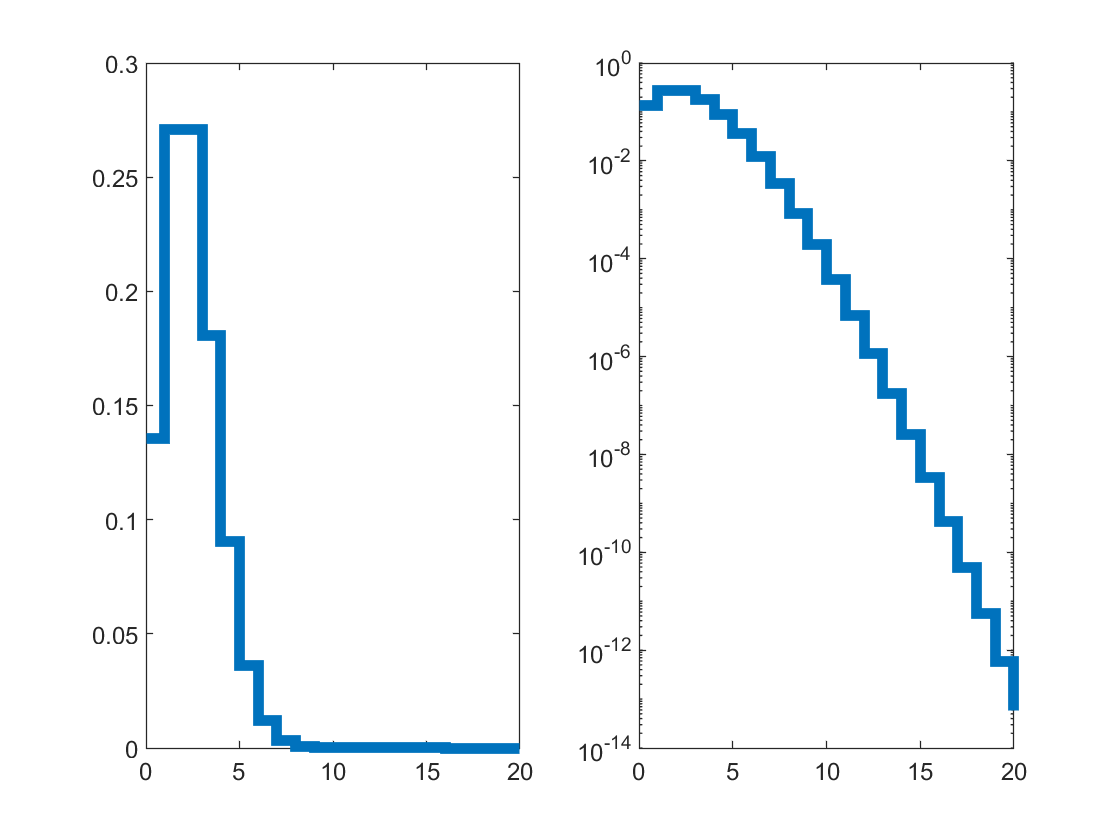

p = 0:20;
poisson = makedist("Poisson",'lambda',2); % Set the mean value for Poisson Distribution to 2.
subplot(1,2,2)
stairs(p, pdf(poisson,p),"LineWidth",4);
set(gca,'YScale','log')
subplot(1,2,1)
stairs(p,pdf(poisson,p),"LineWidth",4);
ylim([0,0.3])
xlim([0,20])

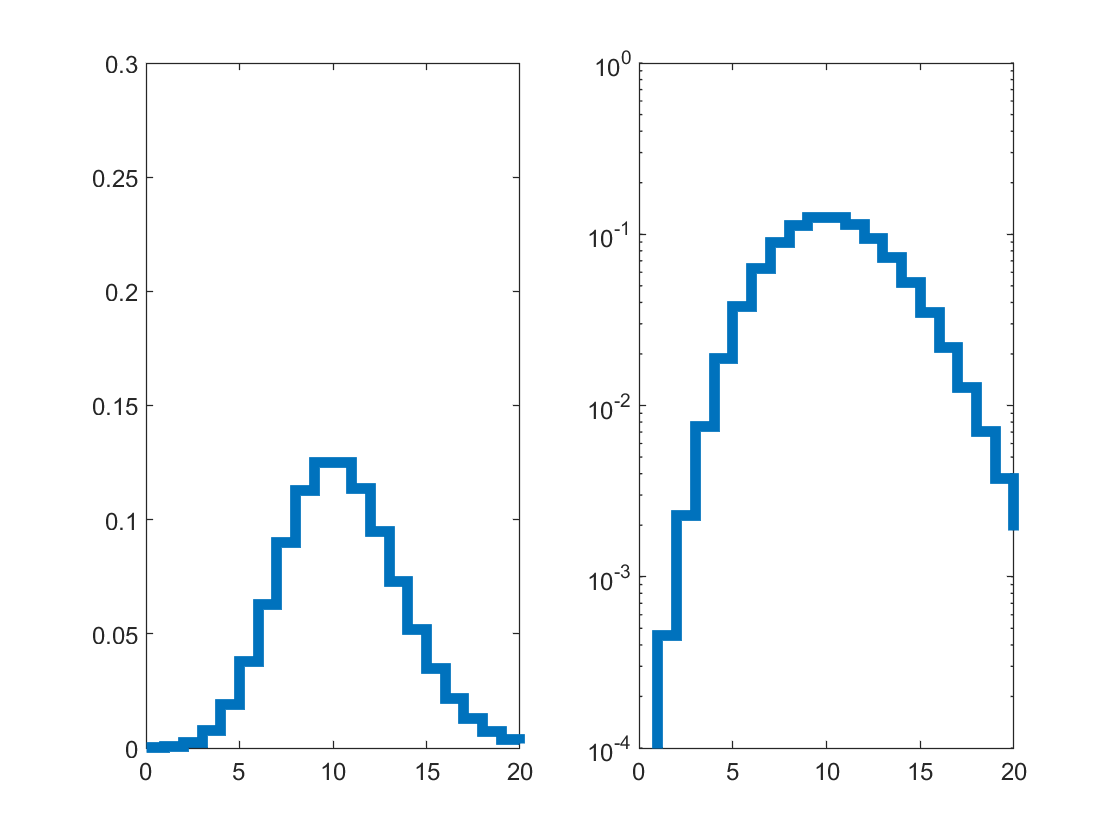

poisson = makedist("Poisson",'lambda',10); % Set the mean value for Poisson Distribution to 5.
subplot(1,2,2)
stairs(p, pdf(poisson,p),"LineWidth",4);
ylim([1e-4,1])
xlim([0,20])
set(gca,'YScale','log')
subplot(1,2,1)
stairs(p,pdf(poisson,p),"LineWidth",4);
% Set the plot for Poisson distribution for each case the same to get a clear view of the trend when parameters changed
ylim([0,0.3])
xlim([0,20]) 

C. What is the probability that this data set of Poisson Distribution with mean value as 10 produces a signal that is equally or more signal-like than what it is like for signal value as 10?

nc = cdf(poisson, 10)

nc = 0.5830

poissonSigma = norminv(nc)

poissonSigma = 0.2097

D.

E. For example, we have 5 data from 1 to 5, all the numbers are integrals, the mean of this Poisson distribution is 2.5. Therefore, we could have such situation that mean value, aka lamda, equals to an non-integral.